# 1. Messung

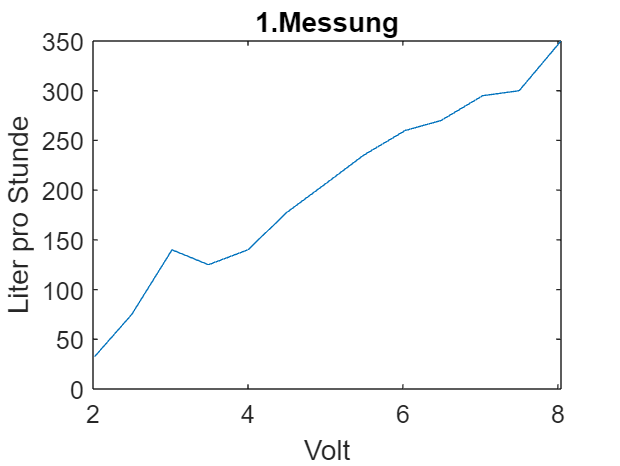

% s= Spannung 
% v= Volumen

s1=[2.02 2.5 3.02 3.49 4 4.5 5.02 5.49 6.03 6.49 7.03 7.50 8.04]; %Einheit Volt
v1= [32.5 75 140 125 140 177.5 207.5 235 260 270 295 300 350]; %Liter pro Stunde
matrix1=[s1' v1'];
plot(s1,v1)
xlabel('Volt')
ylabel('Liter pro Stunde')
title('1.Messung')

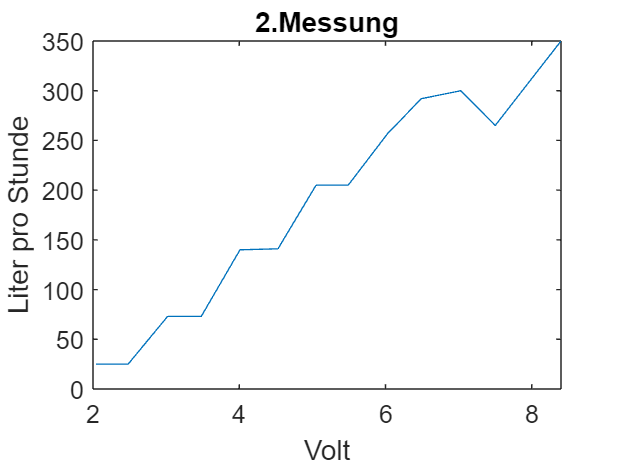





s2=[2.04 2.48 3.02 3.48 4.01 4.53 5.05 5.49 6.03 6.49 7.03 7.5 8.40]; %Einheit Volt
v2=[25 25 73 73 140 141 205 205 257 292 300 265 350]; %Liter pro Stunde
matrix2=[s2' v2'];
plot(s2,v2)
xlabel('Volt')
ylabel('Liter pro Stunde')
title('2.Messung')

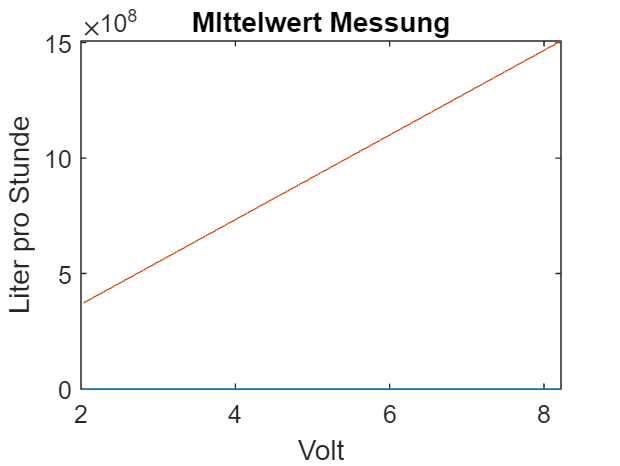



%Mittelwert
s = (s1+s2)/2;
v = (v1+v2)/2;
plot(s,v)
xlabel('Volt')
ylabel('Liter pro Stunde')
title('MIttelwert Messung')
hold on

% Lineare Näherung
p = polyfit(s, v, 1);
K_Ventil = p(1)*3600*1000;
s_linear = K_Ventil*s+p(2);
plot(s,s_linear)